# **Diagram generation**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
m = matfile([dataDir filesep 'gemDbox_alldata.mat']);
% impath = fullfile(dataDir,'C205_Images\');
impath = 'F:\Data\C-Cdt1\Figures\Dryad\Data\C205_diagram_im\fixed\';
impath_mask = 'F:\Data\C-Cdt1\Figures\Dryad\Data\C205_diagram_im\live\';
S = m.S(1,2);
S = S{1};
gate = m.gates_all(1,2);
gate = gate{1};
medEdU = m.medEdU_all(1,2);

xTime = S(1).xTime;
numFrames = S(1).numFrames;

**look at traces**

Gate for early mitosis, first .3 hrs, high/low geminin

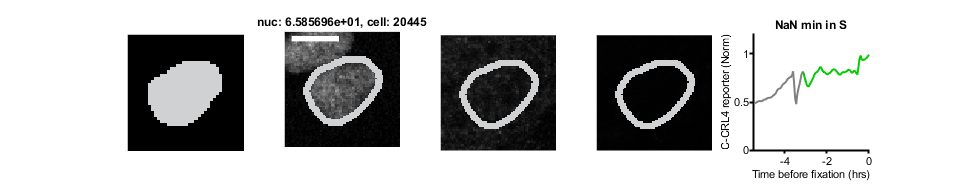

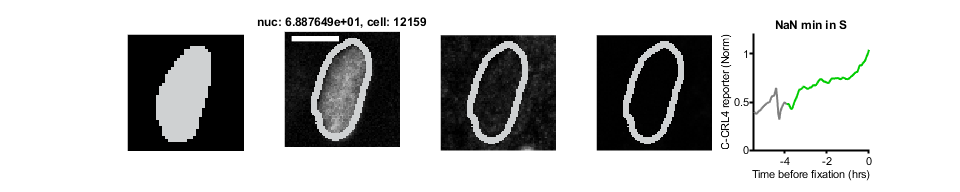

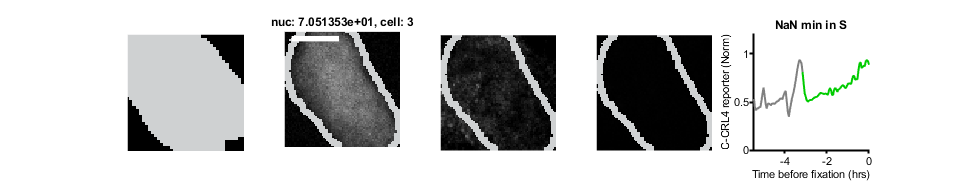

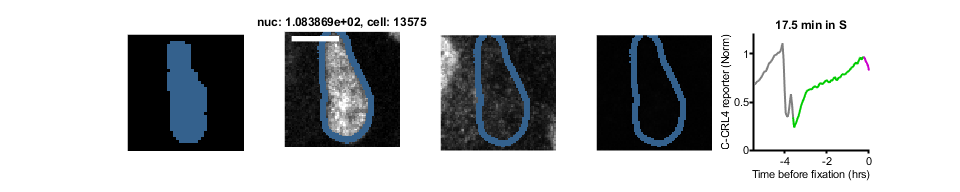

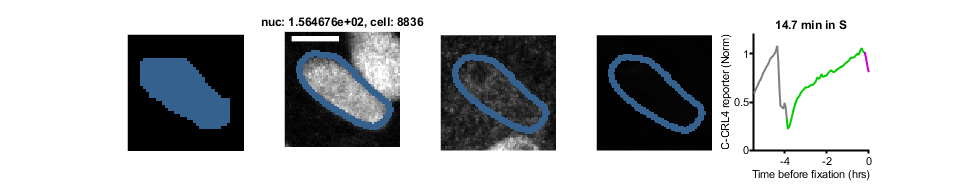

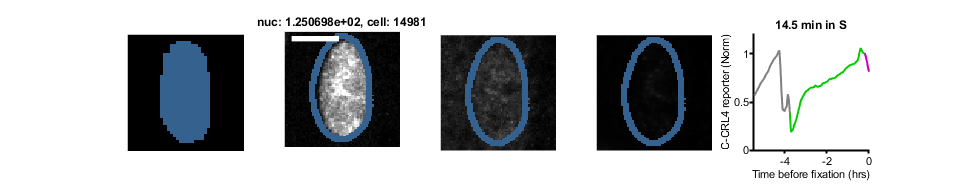

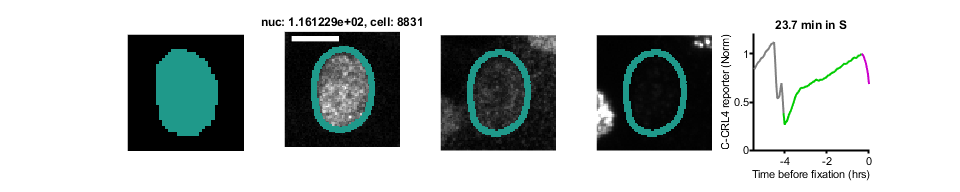

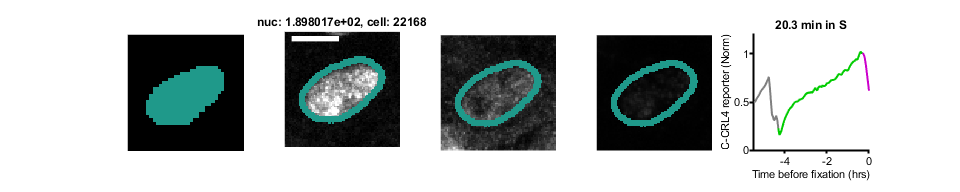

%%% General parameters
cond=1;
poi_align = 4;
sizeBox = 37;
max_cells = 3;
rng(1)
channels = {'_DAPI__round1.tif','_YFP__round1.tif','_YFP__round2.tif','_FarRed__round1.tif'};
ranges = { [0 100], [0 175], [0 200], [0 2000]};
pixel_size = .325; %um/pixel
bar_length = 10/pixel_size;
g1col = [0 .8 0];
scol = [.8 0 .8];
smooth_size = 5;
postbuff = 4;
filtPoints = floor((smooth_size - 1)/2);
exclude = [];

cells_cell = {};
%%% find cells at designated times (G1 cell)
ind = S(cond).POI_time(:,1) >= 3 &  S(cond).POI_time(:,1) <= 4 & isnan(S(cond).POI_time(:,3));
ind = ind & S(cond).YFP2 > prctile(S(cond).YFP2(ind),45) & S(cond).YFP2 < prctile(S(cond).YFP2(ind),55);
find_cells = find(ind);
find_cells = find_cells(~ismember(find_cells,exclude));
num_cells = min([max_cells length(find_cells)]);
rsamp = randsample(length(find_cells),num_cells);
cells_cell = [cells_cell {find_cells(rsamp)}];

%%% find cells at designated times (S cell
S_times = {[0 .3],[.3 .4],[.4 .5],[.5 .75]};
for t = 1:length(S_times)
    g1 = S(cond).POI_time(:,1) - S(cond).POI_time(:,4);
    S_time = S(cond).POI_time(:,poi_align);
    ind = S_time >= S_times{t}(1) &  S_time <= S_times{t}(2) & g1 >= 3 & g1 <=4;
    %     ind = ind & S(cond).YFP2> prctile(S(cond).YFP2(ind),45) & S(cond).YFP2 < prctile(S(cond).YFP2(ind),55);
    find_cells = find(ind);
    find_cells = find_cells(~ismember(find_cells,exclude));
    num_cells = min([max_cells length(find_cells)]);
    rsamp = randsample(length(find_cells),num_cells);
    cells_cell = [cells_cell {find_cells(rsamp)}];
end

colors = viridis;
colors = colors(round(linspace(20,256,length(cells_cell))),:);
colors(1,:) = [207 209 210]/255;

for j = 1:length(cells_cell)
    cells = cells_cell{j};
    
    for i = 1:length(cells)
        %%% Get Cell info
        c = cells(i);
        fixed_shot = [num2str(S(cond).fixedRow(c)),'_',num2str(S(cond).fixedCol(c)),'_',num2str(S(cond).fixedSite(c))];
        fixed_pos = [S(cond).x(c) S(cond).y(c)]/1;
        live_shot = S(cond).shot{c};
        live_pos = squeeze(S(cond).pos(c,end,:)) * 2;
        pois = S(cond).POI(c,:);
        
        %%% Stuff for traces
        crlNuc = smoothdata(S(cond).crlNormAct(c,:),2, 'sgolay',[filtPoints min([postbuff, filtPoints ])], 'omitnan','degree',3);
        offset = max(xTime) ;
        
        im_folder = "F:\Data\C-Cdt1\Figures\Dryad\Data\C205_diagram_im\fixed";
        shot_folder = fullfile(im_folder,fixed_shot,filesep);
        mkdir(shot_folder)
        %%% Load images
        fixed_im= [];
        nuc_mask=imread([impath fixed_shot '\' fixed_shot '_mask.tif']);
%         copyfile([impath fixed_shot '\' fixed_shot '_mask.tif'],fullfile(shot_folder,[fixed_shot '_mask.tif']))
        for ch = 1:length(channels)
            fixed_im(:,:,ch) =imread([impath fixed_shot '\' fixed_shot channels{ch}]);
%             copyfile([impath fixed_shot '\' fixed_shot channels{ch}],fullfile(shot_folder,[fixed_shot channels{ch}]))
        end
         live_folder = "F:\Data\C-Cdt1\Figures\Dryad\Data\C205_diagram_im\live";
        liveshot_folder = fullfile(live_folder,live_shot,filesep);
        mkdir(liveshot_folder)
        live_mask = imread([impath_mask '\' live_shot '\' live_shot '_nucedge_' num2str(numFrames) '.tif']);
        live_mask = imresize(live_mask,2);
%         copyfile([impath_mask '\' live_shot '\' live_shot '_nucedge_' num2str(numFrames) '.tif'],fullfile(liveshot_folder,[live_shot '_nucedge_' num2str(numFrames) '.tif']))

        %%% Create masks
        nuc_fill = imfill(nuc_mask,'holes');
        nuc_label = bwlabel(nuc_fill);
        cell_label = nuc_label(round(fixed_pos(2)),round(fixed_pos(1)));
        cell_mask = nuc_label == cell_label;
        cell_bord = imdilate(cell_mask,strel('disk',2)) - imerode(cell_mask,strel('disk',3));
        
        live_nuc_fill = imfill(live_mask,'holes');
        live_label = bwlabel(live_nuc_fill);
        live_cell_label = live_label(round(live_pos(2)),round(live_pos(1)));
        live_cell_mask = live_label == live_cell_label;
        %     live_cell_bord = imdilate(live_cell_mask,strel('disk',1)) - imerode(live_cell_mask,strel('disk',1));
        live_cell_bord = live_cell_mask;
        
        %%% Crop cell
        cropx = fixed_pos(1) + [-sizeBox sizeBox];
        cropx = round(min(max(cropx,1),size(nuc_mask,1)));
        cropy = fixed_pos(2) + [-sizeBox sizeBox];
        cropy = round(min(max(cropy,1),size(nuc_mask,2)));
        nuc_crop= nuc_mask(cropy(1):cropy(2),cropx(1):cropx(2));
        fixed_im_crop= fixed_im(cropy(1):cropy(2),cropx(1):cropx(2),:);
        cell_crop = cell_bord(cropy(1):cropy(2),cropx(1):cropx(2));
        
        cropx = live_pos(1) + [-sizeBox sizeBox];
        cropx = round(min(max(cropx,1),size(live_mask,1)));
        cropy = live_pos(2) + [-sizeBox sizeBox];
        cropy = round(min(max(cropy,1),size(live_mask,2)));
        live_nuc_crop= live_mask(cropy(1):cropy(2),cropx(1):cropx(2));
        live_cell_crop = live_cell_bord(cropy(1):cropy(2),cropx(1):cropx(2));
        
        %%% Plot trace and image
        figure('units','inches','Position',[0 0 2*5 2])
        subplot(1,5,1)
        hold on
        b = zeros(size(live_nuc_crop));
        %     b = imoverlay(b,live_nuc_crop,'white');
        b = imoverlay(b,live_cell_crop,colors(j,:));
        imshow(b);
        imwrite(b,[pwd() '\Diagram\live_mask_time_' num2str(j) '_cell_' num2str(c) '.tiff'])
        
        subplot(1,5,2)
        hold on
        b = mat2gray(fixed_im_crop(:,:,2),ranges{2});
        %     b = imoverlay(b,nuc_crop,'white');
        b = imoverlay(b,cell_crop,colors(j,:));
        imshow(b);
        plot([5 ,5  +  bar_length], [5, 5 ],'Color','w','LineWidth',4)
        set(gca,'FontSize',8)
        %         t=title({shot, [' x:' num2str(round(x)) ', y:' num2str(round(y))]},'FontSize',8);
        t=title(sprintf('nuc: %d, cell: %d',S(cond).YFP2(c),c),'FontSize',8);
        set(t,'interpreter','none');
        imwrite(b,[pwd() '\Diagram\Cdt1_time_' num2str(j) '_cell_' num2str(c) '.tiff'])
        
        subplot(1,5,3)
        hold on
        b = mat2gray(fixed_im_crop(:,:,3),ranges{3});
        %     b = imoverlay(b,nuc_crop,'white');
        b = imoverlay(b,cell_crop,colors(j,:));
        imshow(b);
        %     imwrite(b,[pwd() '\Diagram\GMNN_time_' num2str(i) '.tiff'])
        
        
        subplot(1,5,4)
        hold on
        b = mat2gray(fixed_im_crop(:,:,4),ranges{4});
        %     b = imoverlay(b,nuc_crop,'white');
        b = imoverlay(b,cell_crop,colors(j,:));
        imshow(b);
        
        
        subplot(1,5,5)
        hold on
        plot(xTime(1:pois(1)) - offset, crlNuc(1:pois(1)),'Color',[.5 .5 .5]);
        if ~isnan(pois(poi_align))
            plot(xTime(pois(1):pois(poi_align)) - offset, crlNuc(pois(1):pois(poi_align)),'Color',g1col);
            plot(xTime(pois(poi_align):end) - offset, crlNuc(pois(poi_align):end),'Color',scol);
        else
            plot(xTime(pois(1):numFrames) - offset, crlNuc(pois(1):numFrames),'Color',g1col);
            
        end
        set(gca,'FontSize',8)
        title(sprintf('%.1f min in S',S(cond).POI_time(c,poi_align)*60),'FontSize',8)
        xlabel('Time before fixation (hrs)','FontSize',8)
        ylabel('C-CRL4 reporter (Norm)','FontSize',8)
        ylim([0 1.2])
        xlim([-5.5 0])
        axis square
        print_pdf([pwd() '\Diagram\images_cond_' num2str(cond) 'cell_' num2str(c) '.pdf'])
        
        
        %     %         imwrite(b,[pwd() '\Figs\C205\small_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])
        %         b = mat2gray(im2crop,range1);
        %     b = imoverlay(b,im1crop,'white');
        %     b = imoverlay(b,cell_crop,'yellow');
        %     figure('units','inches','Position',[0 0 2 2]), imagesc(b)
        %     %         imwrite(b,[pwd() '\Figs\C205\Cdt1_small_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])
        %
        %     b = mat2gray(im4crop,range3);
        %     b = imoverlay(b,im1crop,'white');
        %     b = imoverlay(b,cell_crop,'yellow');
        %     figure('units','inches','Position',[0 0 2 2]), imagesc(b)
        %     %         imwrite(b,[pwd() '\Figs\C205\GMNN_small_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])
        
    end
end